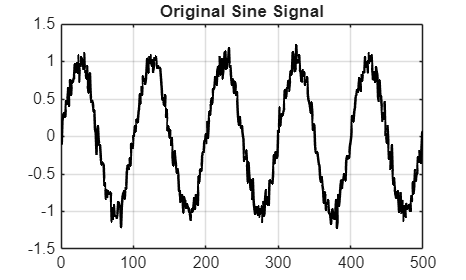

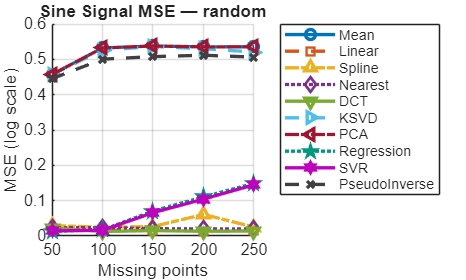

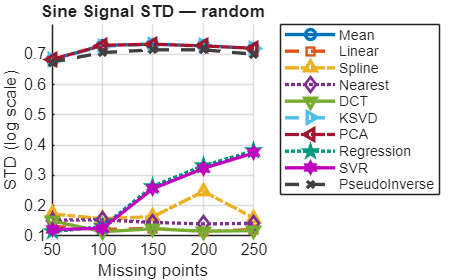

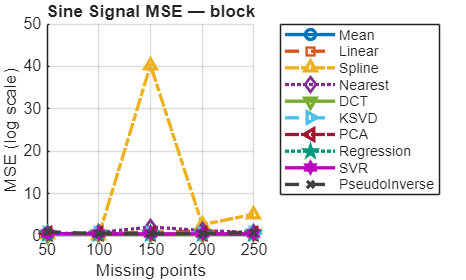

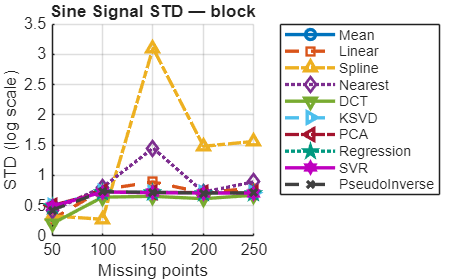

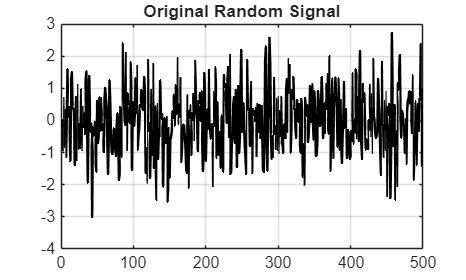

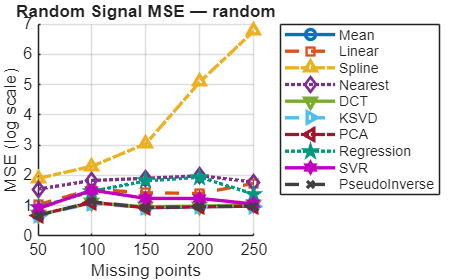

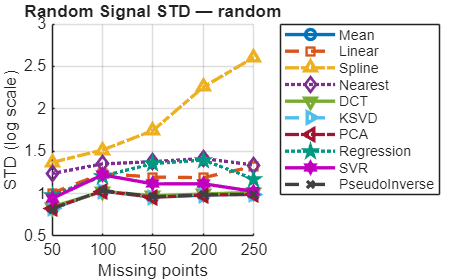

clear
clc
close all

%% ===============================
% STEP 1 — GENERATE SIGNALS
% ===============================

N = 500;

t = linspace(0,10,N)';

x_sine = sin(2*pi*0.5*t) + 0.1*randn(N,1);

x_random = randn(N,1);

signals = {x_sine, x_random};

signal_names = {'Sine Signal','Random Signal'};


%% ===============================
% METHODS
% ===============================

methods = {'Mean','Linear','Spline','Nearest','DCT','KSVD','PCA','Regression','SVR','PseudoInverse'};

num_methods = length(methods);


%% ===============================
% DISTINCT COLORS
% ===============================

plotColors = [

0.00 0.45 0.74   % Mean
0.85 0.33 0.10   % Linear
0.93 0.69 0.13   % Spline
0.49 0.18 0.56   % Nearest
0.47 0.67 0.19   % DCT
0.30 0.75 0.93   % KSVD
0.64 0.08 0.18   % PCA
0.00 0.60 0.50   % Regression
0.75 0.00 0.75   % SVR
0.25 0.25 0.25   % PseudoInverse

];

plotStyles = {'-','--','-.',':','-','--','-.',':','-','--'};

plotMarkers = {'o','s','^','d','v','>','<','p','h','x'};


%% ===============================
% SETTINGS
% ===============================

missing_ratios = 0.1:0.1:0.5;

lossTypes = {'random','block'};


%% ===============================
% MAIN LOOP
% ===============================

for s = 1:length(signals)

x = signals{s};

figure
plot(x,'k','LineWidth',1.5)
title(['Original ',signal_names{s}])
grid on


for lt = 1:length(lossTypes)

lossType = lossTypes{lt};

MSE = zeros(length(missing_ratios),num_methods);

STD = zeros(length(missing_ratios),num_methods);


for r = 1:length(missing_ratios)

ratio = missing_ratios(r);

num_missing = round(ratio*N);


if strcmp(lossType,'random')

mask_pos = randperm(N,num_missing);

else

start_id = randi([1 N-num_missing+1]);

mask_pos = start_id:start_id+num_missing-1;

end


x_test = x;

x_test(mask_pos) = NaN;


%% METHODS

x_mean = fillmissing(x_test,'constant',mean(x_test,'omitnan'));

x_linear = fillmissing(x_test,'linear');

x_spline = fillmissing(x_test,'spline');

x_nearest = fillmissing(x_test,'nearest');

x_dct = dct_imputation(x_test);

x_ksvd = ksvd_imputation(x_test);

x_pca = pca_imputation(x_test);

x_reg = regression_imputation(x_test);

x_svr = svr_imputation(x_test);

x_pinv = pseudoinverse_imputation(x_test);


recons = {x_mean,x_linear,x_spline,x_nearest,x_dct,x_ksvd,x_pca,x_reg,x_svr,x_pinv};


for m = 1:num_methods

err = recons{m}(mask_pos) - x(mask_pos);

MSE(r,m) = mean(err.^2);

STD(r,m) = std(err);

end


end


%% ===============================
% MSE PLOT
% ===============================

figure
hold on

for m = 1:num_methods

semilogy(missing_ratios*N,MSE(:,m),'Color',plotColors(m,:),'LineStyle',plotStyles{m},'Marker',plotMarkers{m},'LineWidth',2,'MarkerSize',6)

end

legend(methods,'Location','bestoutside')

xlabel('Missing points')

ylabel('MSE (log scale)')

title([signal_names{s},' MSE — ',lossType])

grid on



%% ===============================
% STD PLOT
% ===============================

figure
hold on

for m = 1:num_methods

semilogy(missing_ratios*N,STD(:,m),'Color',plotColors(m,:),'LineStyle',plotStyles{m},'Marker',plotMarkers{m},'LineWidth',2,'MarkerSize',6)

end

legend(methods,'Location','bestoutside')

xlabel('Missing points')

ylabel('STD (log scale)')

title([signal_names{s},' STD — ',lossType])

grid on


end

end



%% ===============================
% HELPER FUNCTIONS
% ===============================

function x_hat = dct_imputation(x)

x = x(:);

known = ~isnan(x);

x_fill = x;

x_fill(~known) = mean(x(known));

for i = 1:20

X = dct(x_fill);

X(20:end) = 0;

x_rec = idct(X);

x_fill(~known) = x_rec(~known);

end

x_hat = x_fill;

end



function x_hat = ksvd_imputation(x)

patchSize = 8;

K = 16;

sparsity = 2;

maxIter = 5;

x = x(:);

N = length(x);

known = ~isnan(x);

x_fill = x;

x_fill(~known) = mean(x(known));

D = randn(patchSize,K);

D = D./vecnorm(D);

for iter = 1:maxIter

for i = 1:N-patchSize+1

patch = x_fill(i:i+patchSize-1);

coef = pinv(D)*patch;

[~,idx] = sort(abs(coef),'descend');

coef(idx(sparsity+1:end)) = 0;

patch_rec = D*coef;

x_fill(i:i+patchSize-1) = patch_rec;

end

end

x_hat = x_fill;

end



function x_hat = pca_imputation(x)

x = x(:);

known = ~isnan(x);

x_fill = x;

x_fill(~known) = mean(x(known));

for i = 1:10

[coeff,score,~,~,~,mu] = pca(x_fill);

x_rec = score*coeff' + mu;

x_fill(~known) = x_rec(~known);

end

x_hat = x_fill;

end



function x_hat = regression_imputation(x)

x = x(:);

N = length(x);

known = find(~isnan(x));

unknown = find(isnan(x));

x_fill = x;

for i = unknown'

if i>2 && i<N-2

idx = [i-2 i-1 i+1 i+2];

idx = idx(~isnan(x(idx)));

if length(idx)>=2

mdl = fitlm(idx',x(idx));

x_fill(i) = predict(mdl,i);

else
    
x_fill(i) = mean(x(known));

end

else

x_fill(i) = mean(x(known));

end

end

x_hat = x_fill;

end



function x_hat = svr_imputation(x)

x = x(:);

N = length(x);

known = find(~isnan(x));

unknown = find(isnan(x));

x_fill = x;

for i = unknown'

if i>2 && i<N-2

idx = [i-2 i-1 i+1 i+2];

idx = idx(~isnan(x(idx)));

if length(idx)>=2

mdl = fitrsvm(idx',x(idx),'KernelFunction','gaussian');

x_fill(i) = predict(mdl,i);

else

x_fill(i) = mean(x(known));

end

else

x_fill(i) = mean(x(known));

end

end

x_hat = x_fill;

end



function x_hat = pseudoinverse_imputation(x)

x = x(:);

known = ~isnan(x);

t = (1:length(x))';

Phi = [ones(size(t)) t t.^2 t.^3];

c = pinv(Phi(known,:))*x(known);

x_hat = Phi*c;

x_hat(known) = x(known);

end